% Linear elements - Displacement of bar due to load at free end, fixed at another
clc,clearvars,format compact,close all
E = input("Young's Modulus of bar material: ");
l = input("Length of bar: ");
A_l = input("cross section Area at the free end: ");
P = input("Value of force applied at end: ");
n = input("Input array of no. of linear elements to discretize: ");
disp_end_lin = [];
for i = 1:length(n)
 e_n = zeros(n(i),2); %element node connectivity relation
 for j = 1:n(i)
 e_n(j,:) = [j j+1]; %i th row gives i th element's node connectivity
 end
 l_e = l/n(i); %Length of each element
 no_nodes = max(e_n,[],'all'); %no. of nodes
 force = zeros(no_nodes,1);
 stiffness = zeros(no_nodes);
 displacement = zeros(no_nodes,1);

 g = 1;
 h = setdiff(1:no_nodes,g);
 r = no_nodes;
 force(r,1) = P;
 reduced_force = force(h, :);
 %Creating Stiffness matrix
 for j = 1:n(i)

 t = 3 - (((2*j)-1)/n(i));
 T = (E*A_l*t)/l_e;
 r = e_n(j,1); % left node no. of element j
 s = e_n(j,2); % right node no. of element j
 stiffness(r,r) = stiffness(r,r) + T;
 stiffness(s,s) = stiffness(s,s) + T;
 stiffness(r,s) = stiffness(r,s) - T;
 stiffness(s,r) = stiffness(s,r) - T;
 end
 zero_disp_nodes = g;
 active_nodes = setdiff(1:no_nodes,zero_disp_nodes); % nodes with unknown
displacement
 reduced_stiffness = stiffness;
 reduced_stiffness = reduced_stiffness(:,active_nodes); %A([3,9],:) = []; Deletes rows
 reduced_stiffness = reduced_stiffness(active_nodes,:); %keeps rows and columns of active nodes in stifness matrix in order to solve for unknown displacements.
 unknown_disp = inv(reduced_stiffness)*reduced_force;
 for j = 1:length(active_nodes)
 displacement(active_nodes(j)) = unknown_disp(j);
 end
 fprintf("\n%d linear elements", n(i))
 fprintf("\nDisplacement at end = %d", displacement(no_nodes))
 disp_end_lin(end+1) = displacement(no_nodes);
end

displacement =      0
     0
     0


2 linear elements


Displacement at end = 5.333333e-03

displacement =      0
     0
     0
     0
     0


4 linear elements


Displacement at end = 5.448773e-03

displacement =      0
     0
     0
     0
     0
     0
     0


6 linear elements


Displacement at end = 5.472906e-03

displacement =      0
     0
     0
     0
     0
     0
     0
     0
     0


8 linear elements


Displacement at end = 5.481624e-03

displacement =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


10 linear elements


Displacement at end = 5.485710e-03

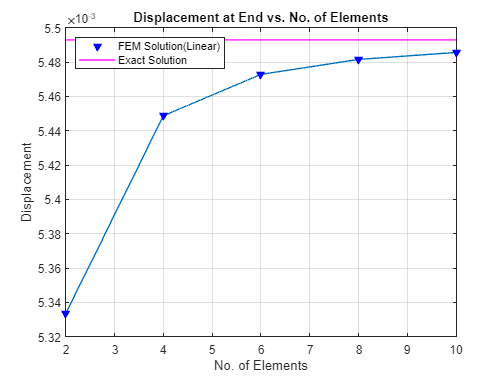

%Plotting
X = n;
Y = disp_end_lin;
plot(X,Y);
hold on
plot(X,Y,'bv','MarkerFaceColor','b');
title('Displacement at End vs. No. of Elements')
ylabel('Displacement')
xlabel('No. of Elements')
grid on
analy_soln = (P*l*log(3))/(2*E*A_l);
yline(analy_soln,'m','LineWidth',1.5)
legend('','FEM Solution(Linear)','Exact Solution','Location','Northwest','Orientation','vertical');